%*********************************************************************************************%
% Assume the size of Room is 10m * 10m *4m and the only LED in the ceil of the center of room %
% We define the lower left corner as the origin point (0, 0, 0) and the                       %
% other three point is (0, 10, 0), (10, 0, 0), (10, 10, 0), the coordinate                    %
% of the LED in this Coordinate system is (5, 5, 4). The Normal Vector of                     %
% LED is constant (0, 0, -1) in our consider(in most case this is                             %
% reasonable because the fixed LED installation Method), and the Normal                       %
% Vector of PD is random because of the rotation and moving, But we think                     %
% we can get this information throught the internal sensor of the phone                       %
%*********************************************************************************************%
%Summary                                                                                      %
%Size of the room 10m * 10m *4m                                                               %
%Coordinate of LED (5, 5, 4)                                                                  %
%Normal Vector of LED (0, 0, -1)                                                              %
%*********************************************************************************************%
tic
clear clc
syms P_pd x y z
AR    = 1; %Recieve are of pd (unit:cm^2)
P_Ti  = 1;%Transmit power of led (unit:unknown)
X_led = [0  0 -1];
X_pd  = [0  0  1];
P_led = [5  5  4];
P_pd  = [x  y  z];
D_led = P_pd  - P_led;
D_pd  = P_led - P_pd;
Theta = dot(D_led,X_led)/(norm(D_led,2)*norm(X_led,2)) %Irradiance Angle(Cos value)

$$Theta = -\frac{\bar{z}-4}{\sqrt{{\left|x-5\right|}^{2}+{\left|y-5\right|}^{2}+{\left|z-4\right|}^{2}}}$$

Psi   = dot(D_pd,X_pd)/(norm(D_pd,2)*norm(X_pd,2)) %Incidence Angle

$$Psi = -\frac{\bar{z}-4}{\sqrt{{\left|x-5\right|}^{2}+{\left|y-5\right|}^{2}+{\left|z-4\right|}^{2}}}$$

Self_Power_Angle_led = 60; 
Self_Power_Angle_pd  = 60;
m = -log(2) /log(cos(Self_Power_Angle_led/180*pi)) %Lambertian Order of led

m = 1.0000

M = -log(2) /log(cos(Self_Power_Angle_pd/180*pi))  %Lambertian Order of pd

M = 1.0000

P_Theta_Psi = (m+1)*AR*P_Ti*(Theta^m*Psi^M)/(2*pi*(norm(D_led,2)^2))

$$P\_Theta\_Psi = \frac{{\left(\bar{z}-4\right)}^{2}}{\pi \,{\left({\left|x-5\right|}^{2}+{\left|y-5\right|}^{2}+{\left|z-4\right|}^{2}\right)}^{2}}$$

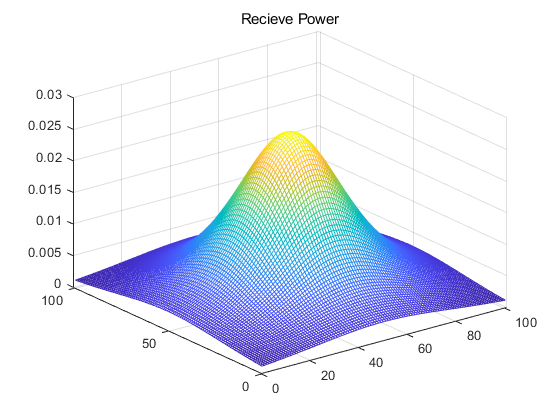



%********************Calculate the recieve power at different position***********************%
x_scale = 0:0.1:10;
y_scale = 0:0.1:10;
z_scale = 0.5;
P = zeros(length(x_scale),length(y_scale));
C_P = zeros(length(x_scale),length(y_scale));
C_T = zeros(length(x_scale),length(y_scale));
D = zeros(length(x_scale),length(y_scale));

for i = 1:length(x_scale)
    parfor j = 1:length(y_scale)
            x = x_scale(i);
            y = y_scale(j);
            z = z_scale;
            P_pd = [x y z];
            D_led = P_pd  - P_led;
            D_pd  = P_led - P_pd;
            Theta = dot(D_led,X_led)/(norm(D_led,2)*norm(X_led,2)); %Irradiance Angle
            Psi   = dot(D_pd,X_pd)/(norm(D_pd,2)*norm(X_pd,2)); %Incidence Angle
            Psi(Psi<=0) = 0;    %Incidence Angle maybe larger than 90, in this case we handle it as 90


            P(i,j) = (m+1)*AR*P_Ti*(Theta^m*real(Psi^M))/(2*pi*(norm(D_led,2)^2));
            C_P(i,j) = acos(Psi)/pi*180;
            C_T(i,j) = acos(Theta)/pi*180;
            D(i,j) = norm(D_led,2);
    end
end

mesh(P)
title('Recieve Power')

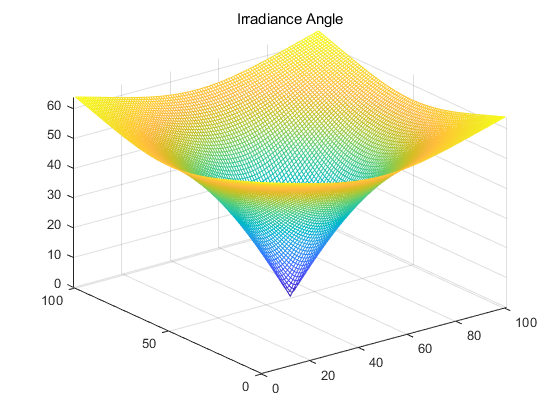

figure
mesh(C_T)
title('Irradiance Angle')

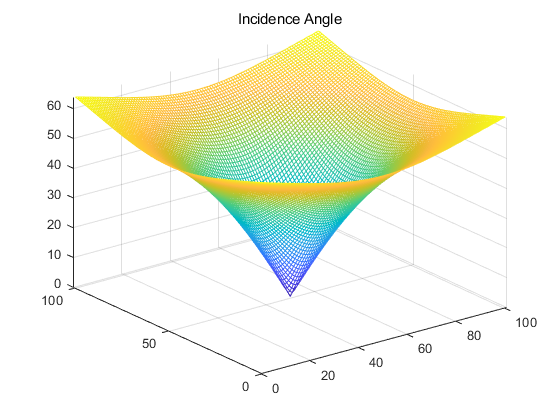

figure
mesh(C_P)
title('Incidence Angle')

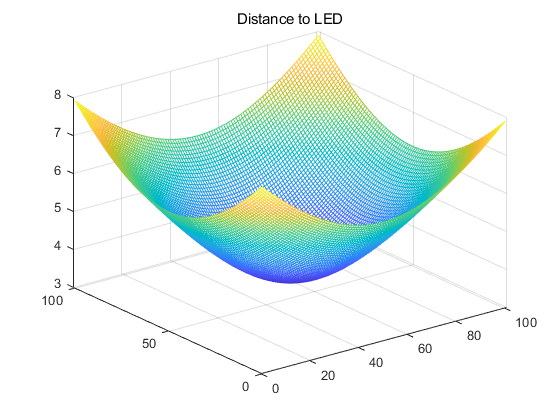

figure
mesh(D)
title('Distance to LED')

%[row,col]=find(P==max(max(P)))
